Calculates the normalized force in tendon for Thelen2003 muscle model.

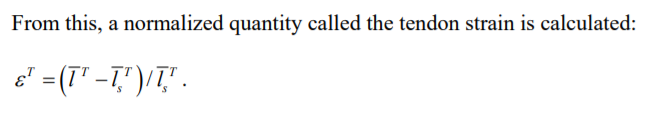

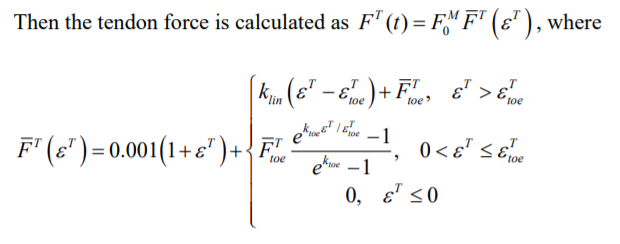

function FT = Thelen2003_Tendon_Force(norm_ten_len)
    % define constants for tendon force calculation
    eT_0 = 0.04; % tendon strain due to maximum isometric force
%     eT_toe = 0.609*eT_0; % tendon strain above which tendon force is linear with respect to tendon strain
    FT_toe = 33/100; % normalized tendon force above which tendon force is linear with respect to tendon strain
    t1 = exp(3);
    eT_toe = (0.99e2*eT_0*t1) / (0.166e3*t1 - 0.67e2);
%     k_lin = 1.712/eT_0; % a linear shape factor
    k_lin = (0.67e2/0.100e3) * 1.0/(eT_0 - (0.99e2*eT_0*t1) / (0.166e3*t1 - 0.67e2));
    k_toe = 3; % an exponential shape factor
    
    FT = zeros(size(norm_ten_len));
    for i = 1:length(norm_ten_len)
        eT = norm_ten_len(i) - 1;
        
%         FT_1 = 0.001 * (1 + eT);
        if eT > eT_toe
%             FT(i) = FT_1 + k_lin * (eT - eT_toe) + FT_toe;
            FT(i) = k_lin*(eT - eT_toe) + FT_toe;
        elseif eT > 0
%             FT(i) = FT_1 + FT_toe * (exp(k_toe*eT/eT_toe) - 1) / (exp(k_toe) - 1);
            FT(i) = (FT_toe/exp(k_toe) - 1) * (exp(k_toe * eT/eT_toe) - 1);
        else
            FT(i) = 0;
        end
    end

end